# Plot projections of L-shell

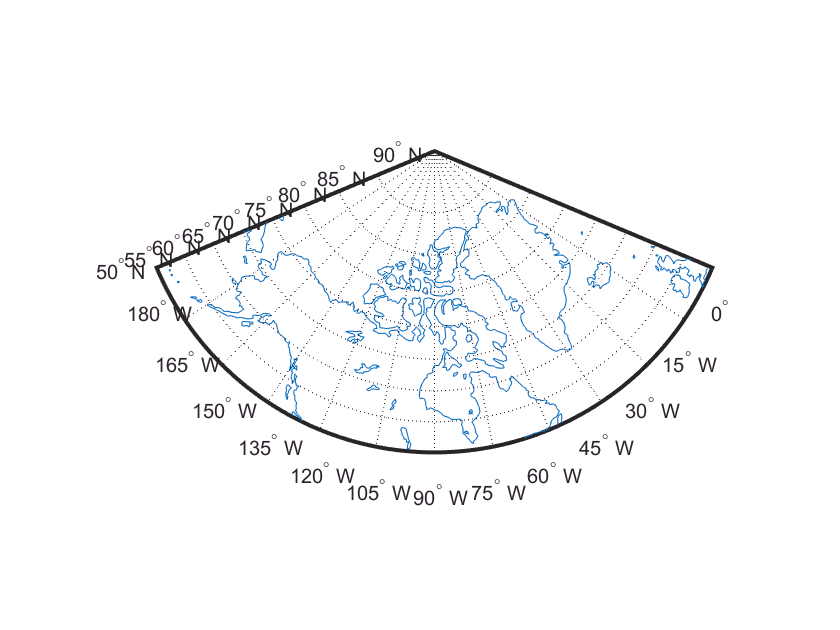

figure;
ax1=axesm('lambertstd','MapLatLimit',[50, 90],'MapLonLimit',[-180,0],...
    'Frame','on','Grid','on','MeridianLabel','on','ParallelLabel','on',...
    'PLineLocation',5,'MLineLocation',15);
axis off
load coastlines

plotm(coastlat,coastlon)

## L-shell

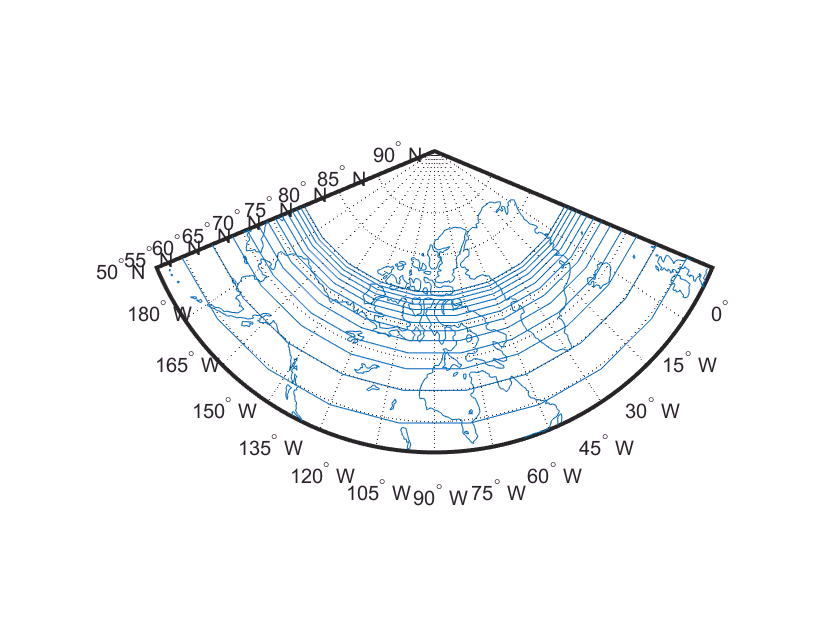

for i=1:1:15
    L=1+1*(i-1);
    RE=6.37*10^6;
    r = 6.37*10^6 + 10^5;
    lambda=acos(sqrt(r/(L*RE)));
    L_lat=radtodeg(lambda);
    hold on;
    x=L_lat*ones(10,1);
    y=linspace(-180,0,10)';
    plotm(x,y);
end